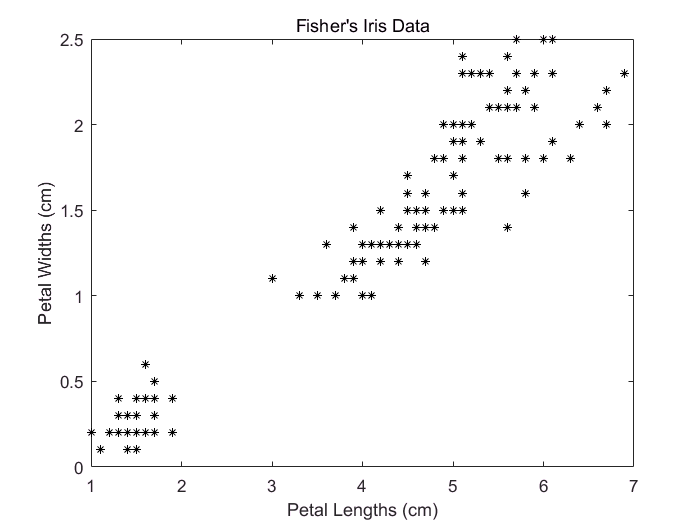

load fisheriris
X = meas(:,3:4);

figure;
plot(X(:,1),X(:,2),'k*','MarkerSize',5);
title 'Fisher''s Iris Data';
xlabel 'Petal Lengths (cm)'; 
ylabel 'Petal Widths (cm)';

rng(1); % For reproducibility
[idx,C] = kmeans(X,3);
x1 = min(X(:,1)):0.01:max(X(:,1));
x2 = min(X(:,2)):0.01:max(X(:,2));
[x1G,x2G] = meshgrid(x1,x2);
XGrid = [x1G(:),x2G(:)]; % Defines a fine grid on the plot

idx2Region = kmeans(XGrid,3,'MaxIter',1,'Start',C);

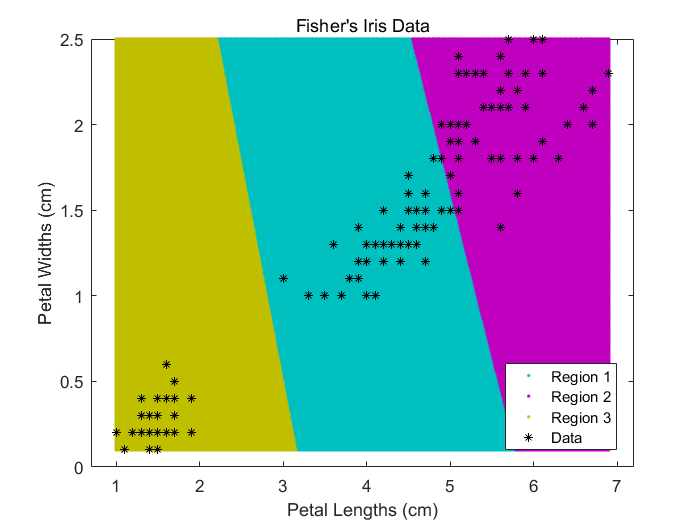

figure;
gscatter(XGrid(:,1),XGrid(:,2),idx2Region,...
    [0,0.75,0.75;0.75,0,0.75;0.75,0.75,0],'..');
hold on;
plot(X(:,1),X(:,2),'k*','MarkerSize',5);
title 'Fisher''s Iris Data';
xlabel 'Petal Lengths (cm)';
ylabel 'Petal Widths (cm)'; 
legend('Region 1','Region 2','Region 3','Data','Location','SouthEast');
hold off;